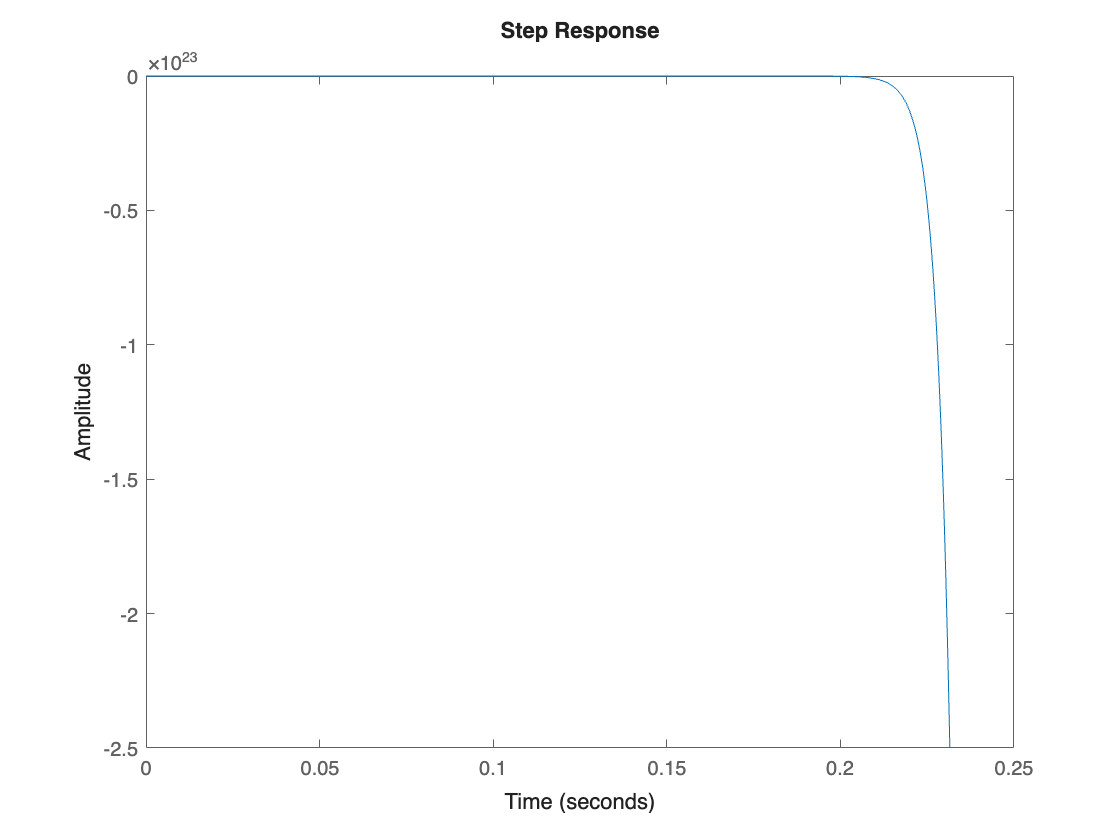

s = tf('s');

% Plant
G = -21280 / (0.029*1e3*s^2 - 1886826.67);
stepplot(G)

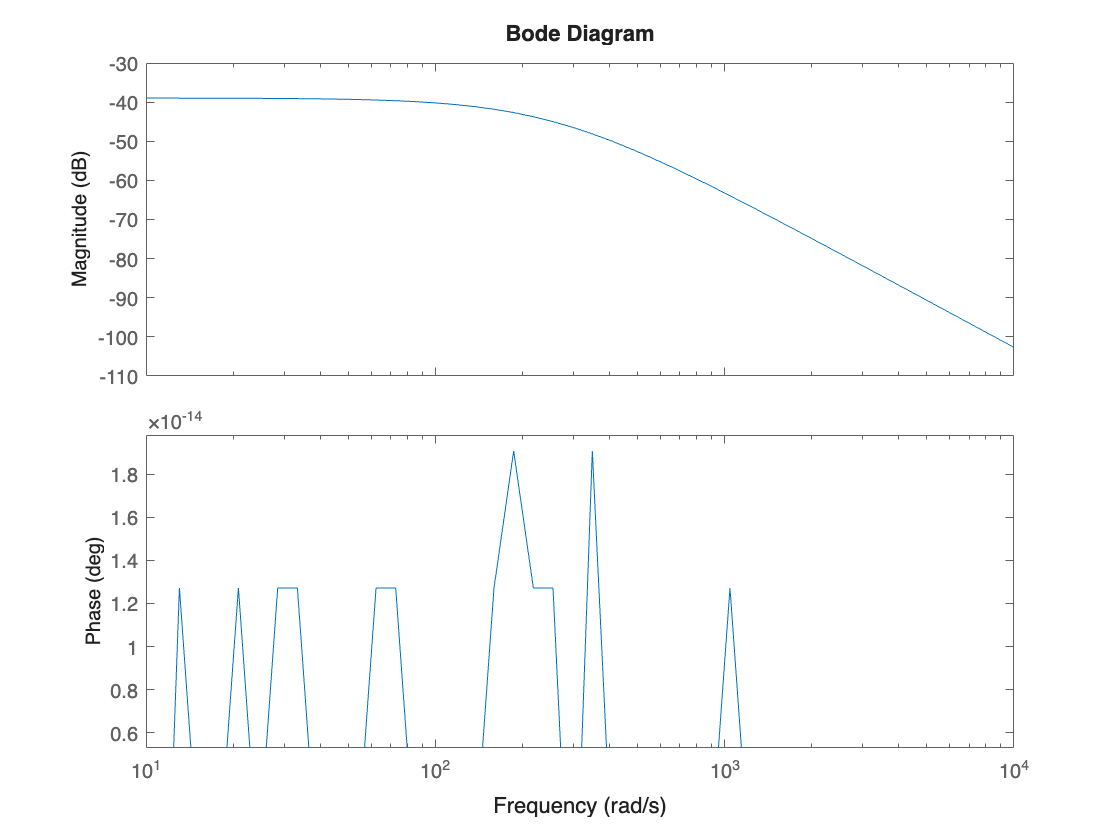


% Bode + Nyquist
bodeplot(G)

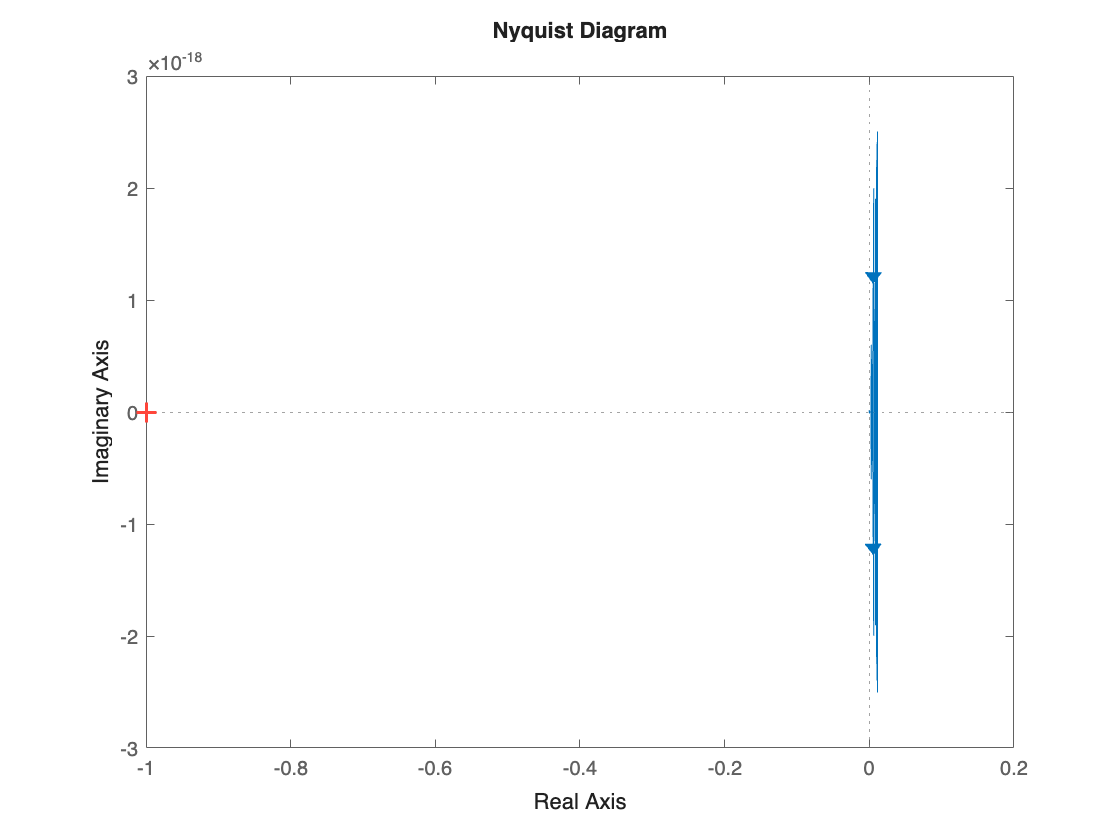


nyquistplot(G)

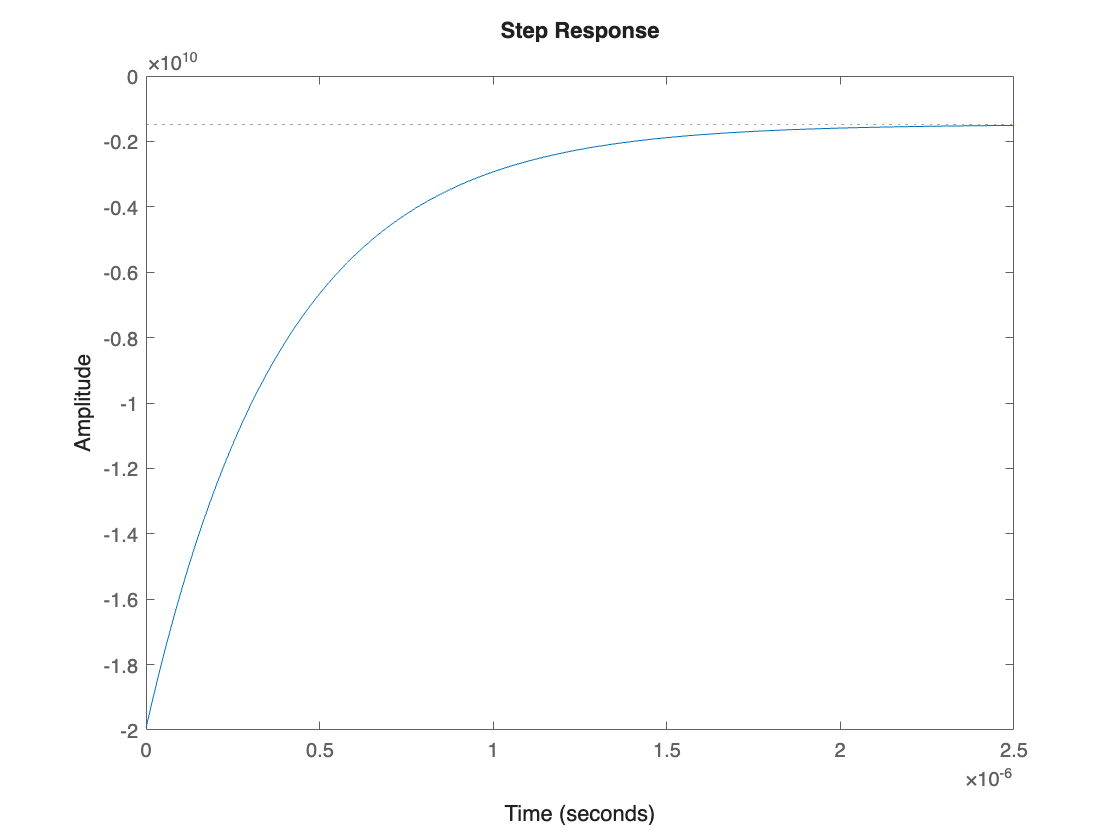


% Controller
C = -1.9946e10*(s+1.885e5)/(s+2.543e6);
stepplot(C)

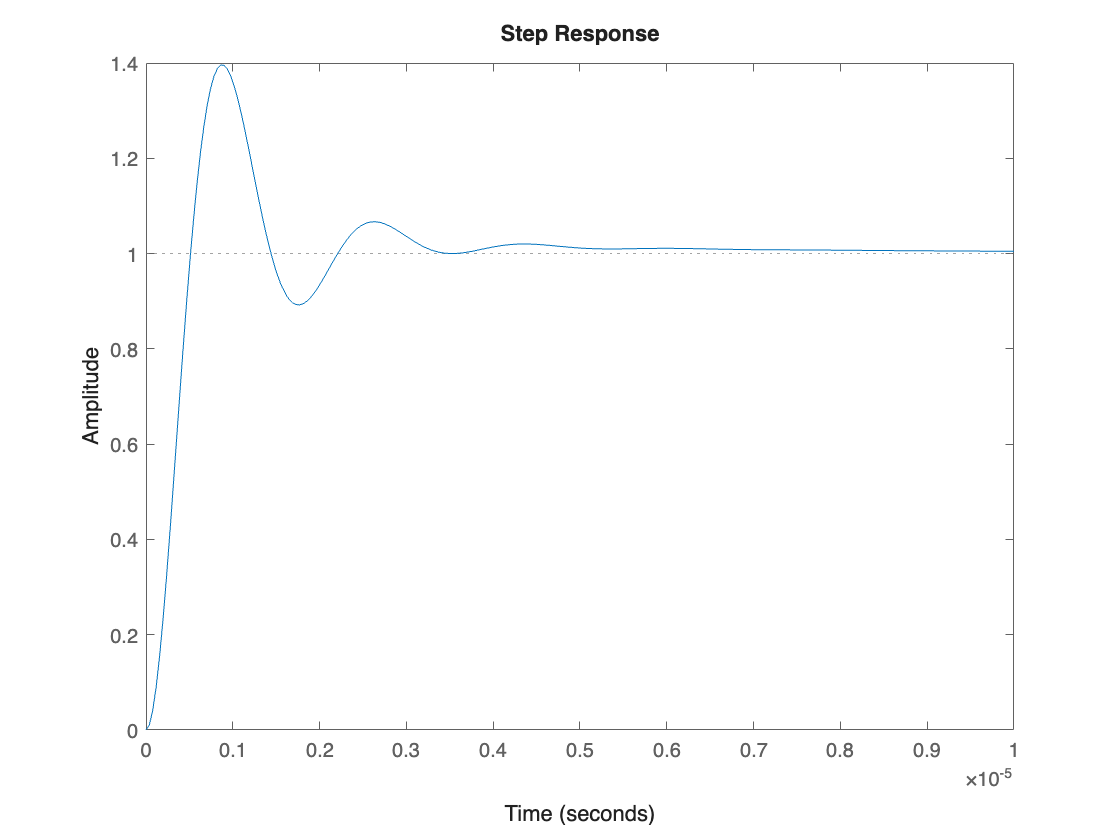


% Outer loop
T = feedback(G*C, 1);
stepplot(T)

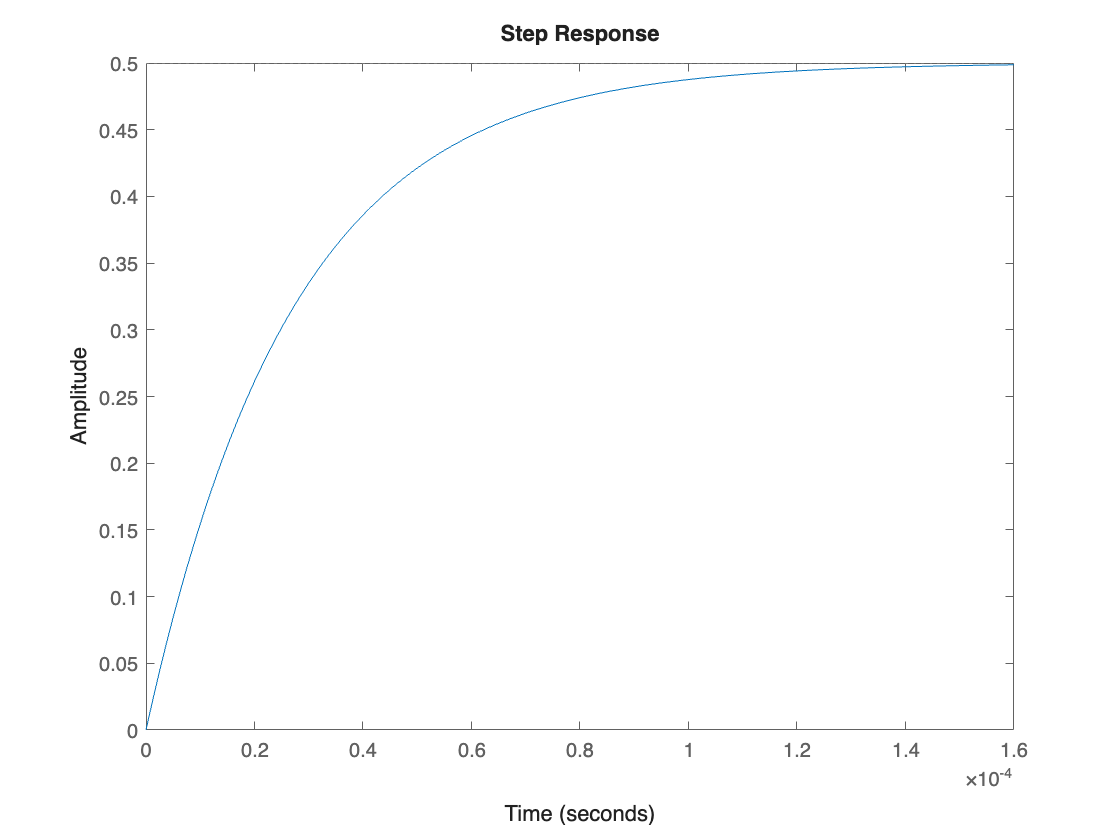


% Current loop plant
G2 = 1/(5.41e-5*s + 2);
stepplot(G2)

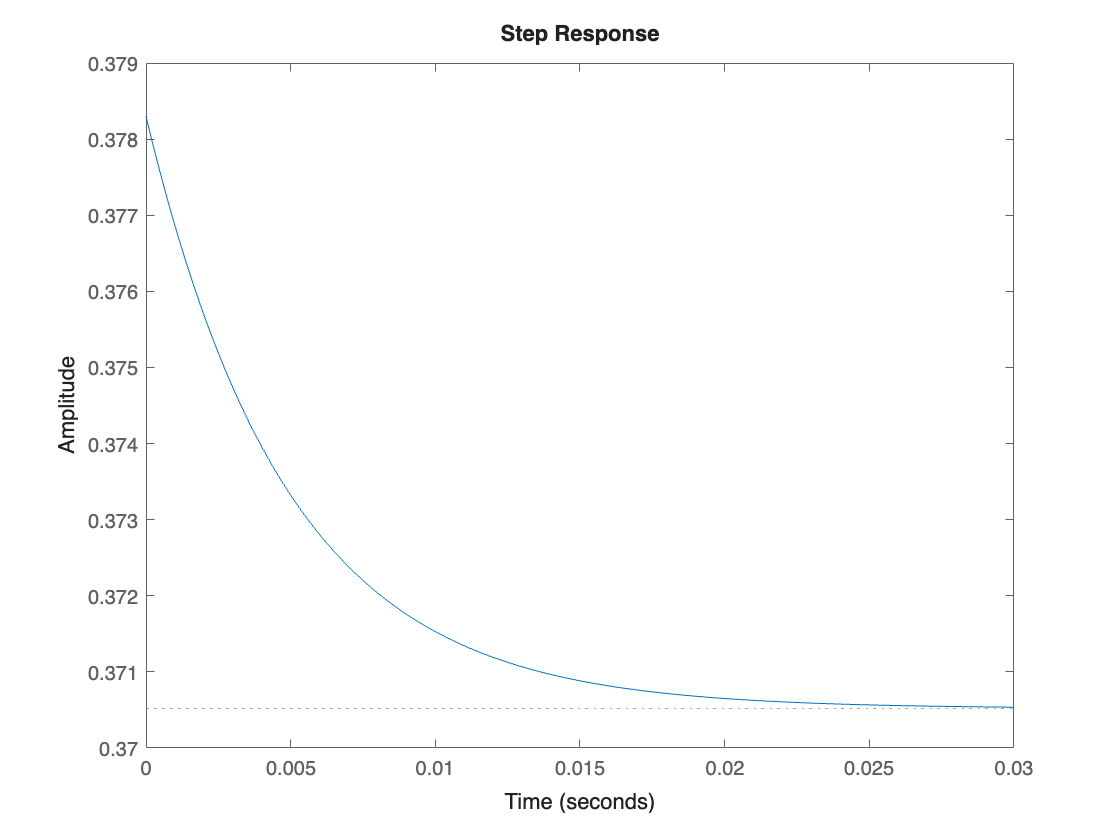


% Current controller
%C2 = (3783*(s+200))/(0.0001*(s+204.2));
C2 = (0.3783*(s+200))/(s+204.2);
step(C2)

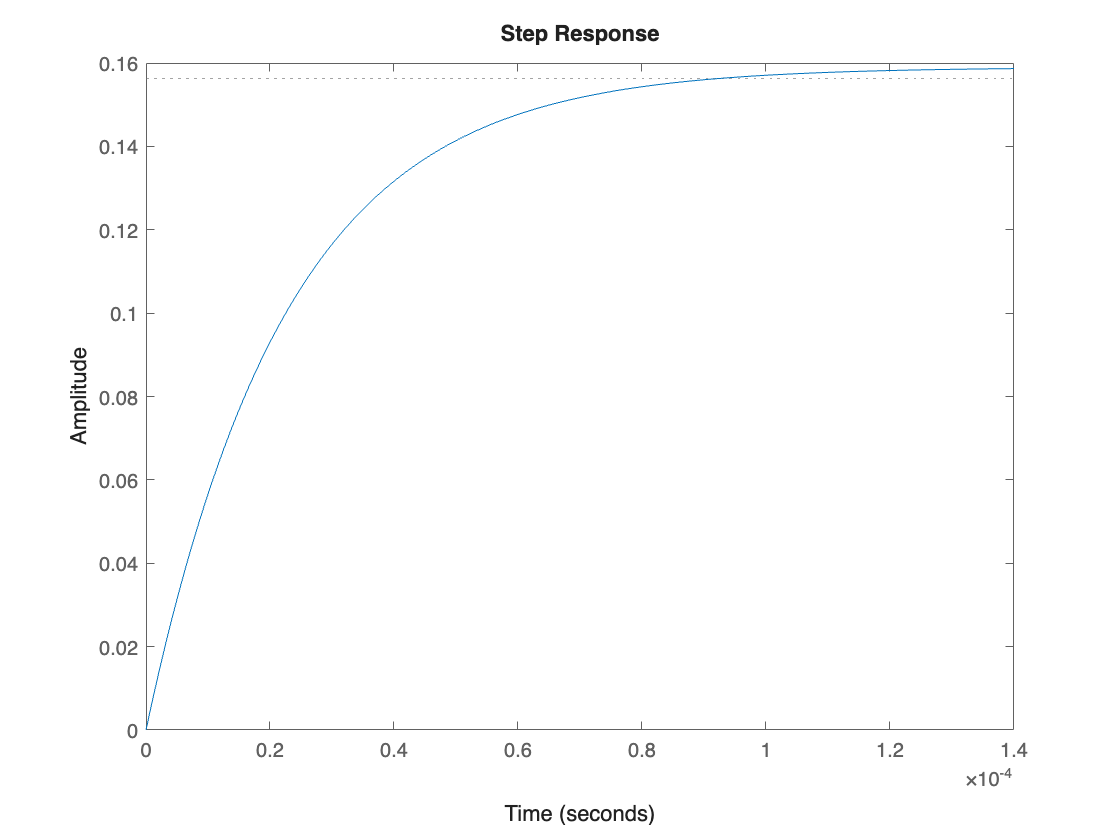

% Inner loop with current controller
T2 = feedback(G2*C2, 1);
stepplot(T2)

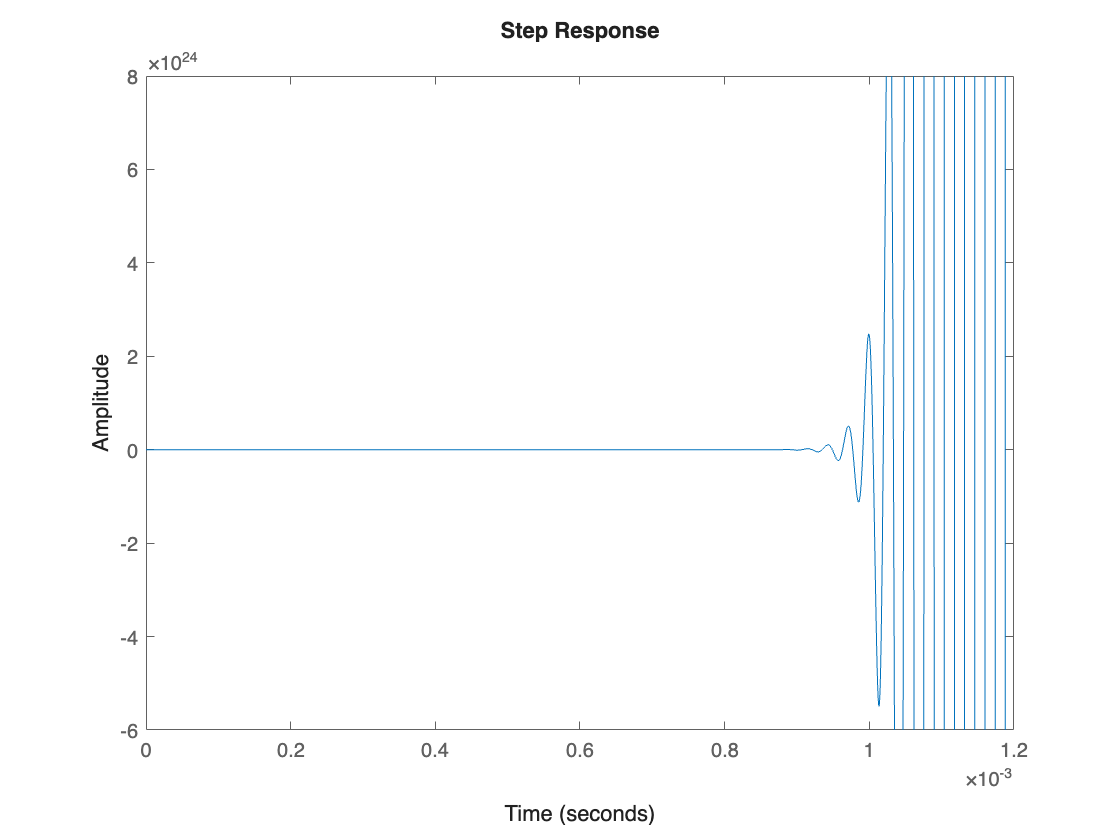


% Final cascaded system
T3 = feedback(T2*C*G, 1);
stepplot(T3)